**INTRO TO MONTE CARLO METHODS:**

Example 7.6 + Example 7.7

H0: mu = 454

HA: mu < 454

Step 1: Calculate the observed value of the test statistic (t_0) from the given data.

This is a preliminary step.

mcdata = importdata('C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\mcdata.mat');
n = length(mcdata);
sigma = 7.8;
sigmaxbar = sigma/sqrt(n);
tobs = (mean(mcdata)-454)/sigmaxbar

tobs = -2.5641

Step 2: Decide on a pseudo-population that reglect the characteristics of the true population under the null hypothesis. It appears that a normal distribution with sigma = 7.8 is a good model.

Step 3, Step 4, and Step 5:

M = 1000; % number of MC trials.

t_stats = zeros(1,M);

% the MC simulations:
for i = 1:M
    xs = normrnd(454, sigma, 1, n);
    t_stats(i) = (mean(xs) - 454)/sigmaxbar;
end

Step 6: get the estimated critical value

alpha = 0.05;
t_stats = sort(t_stats);
mc_tstat = t_stats(round(alpha*M))

mc_tstat = -1.5825

From the above output, we get a test statistic that is certainly greater than the test statistic calculated from the original data (t_0). The test statistic we calculated above is the critical region. Because t_0 falls deep inside the critical region, we would reject H0.

We can calculate a corresponding p-value using the following code to reach the same conclusion as above:

ind = find(t_stats <= tobs);
pval = length(ind)/M

pval = 0.0030

Because the p-vallue is so small, we would reject H0.

Example 7.8

Cool, so we were able to use MC simulations to conclude that in fact the population parameter is less than 454. We can now calculate the significance level of the above test (alpha), and check the Type II Error in the following code:

% type I error
cv = norminv(alpha, 0, 1);
alph_instance = 0;

for i = 1:M
    xs = normrnd(454,sigma, 1, n);
    t_stats = (mean(xs)-454)/sigmaxbar;
    if t_stats <= cv
        alph_instance = alph_instance + 1;
    end
end

alphahat = alph_instance/M

alphahat = 0.0500

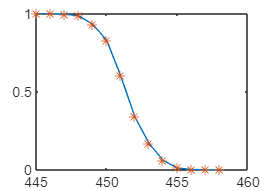

% alphahat is very close to 0.05!


% type II error
% get some alternative hypothesis
mualt = 445:458;
betahat = zeros(size(mualt));

for j = 1:length(mualt)
    beta_instance = 0;
    mu = mualt(j);
    for i = 1:M
        xs = normrnd(mu, sigma, 1, n);
        t_stats = (mean(xs)-454)/sigmaxbar;
        if t_stats > cv
            beta_instance = beta_instance + 1;
        end
    end
    betahat(j) = beta_instance/M;
end

powhat = 1 - betahat;
plot(mualt, powhat)
hold on
plot(mualt, powhat, "*")

Above is a plot of the estimated power as a function of mu. Notice that as the true value for mu gets closer to 454 (the mean under H0), the power of the test decreases.

Recall that the power of a test is the probability of rejecting the null hypothesis, when in fact it is false.

**BOOTSTRAP METHODS:**

The book refers to bootstrapping as a method where resampling is taken from the original sample. The prior example IS NOT bootstrapping as it is resampling from a pseudo-population. Because of this, bootstrapping is considered non-parametric.

Example 7.9:

This example offers our first insight into how bootstrapping works. We use the provided data to estimate the skewness of the population. We then estimate the standard error of this statitic using the bootstrap method.

forearm = importdata('C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\forearm.mat');
n = length(forearm)

n = 140

B = 200; % bootstrap estimates.
theta = skewness(forearm) % statistic of interest.

theta = -0.1092


% use unidrnd to get the indeces to the resamples.
% each column corresponds to indices for a bootstrap resample.
inds = unidrnd(n,n,B);

% extract values from the data.
xboot = forearm(inds);

% obtain skewness for each column.
theta_boot = skewness(xboot);
se_boot = std(theta_boot)

se_boot = 0.1373

Above, the se_boot value produces the estimated standard error in skewness. This is how to calculate this value WITHOUT the Statistics Toolbox function. The following set of code uses the bootstrp function:

Bmat = bootstrp(B,@skewness,forearm);
se_bmat = std(Bmat)

se_bmat = 0.1337

The simplicity of the above code is phenomenal.

So far, we've only covered how to calculate the standard error of out parameter of interest using the bootstrap method.

Another way to measure the performance of estimating the parameter of interest is bias. Bias is worth stuying as it helps us understand how to correct it.

The following code shows how to estimate the bias in the sample skewness from the forearm data. NOTE: this uses the code from the unidrnd() section.

mean_boot = mean(theta_boot);
bias_boot = mean_boot - theta

bias_boot = -0.0063

It's important to note that the above bias is small relative to the standard error.

Now that we know how to calculate the standard error and bias of our statistic, we can now discuss bootstrap Confidence Intervals (CI). There are three types that can be calculated:

**Bootstrap Standard CI**

The CI are based on the standard normal distribution, making them parametric. When calculating these confidence intervals, we'll be using SE_{theta-hat}, which is the standard error for the statistic theta-hat, obtained using the bootstrap.

**Bootstrap-t CI**

DAMN. I don't even want to begin explaining this shit. Consider the following example, in this case we are interested in estimating the variance of the forearm data, and we decide to use the formula for population variance as a statistic. Just like the book, I'm using a pre-built function called mom(x) to calculate the sample second central moment:

Example 7.11

forearm = importdata('C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\forearm.mat');
n = length(forearm);
alpha = 0.1;
B = 1000;
thetahat = mom(forearm);

% get bootstrap replicates and indeces respectively.
[bootreps, bootsam] = bootstrp(B, 'mom', forearm);

% set up storage space for se's
sehats = zeros(size(bootreps));

for i = 1:B
    % extract the sample from the data.
    xstar = forearm(bootsam(:,i));
    sehats(i) = std(bootstrp(25, 'mom', xstar));
end

zvals = (bootreps - thetahat)./sehats;

% estimate the se using the bootstrap
se = std(bootreps)

se = 0.1325


% attain quantiles needed for interval
k = B*alpha/2;
szval = sort(zvals);
tlo = szval(k);
thi = szval(B-k);

% endpoints of interval
blo = thetahat - thi*se

blo = 1.0515

bhi = thetahat - tlo*se

bhi = 1.5104

This code is a lot easier than it seems. Notice that the standard error for each bootstrap in the for loop is calculated to find z-values. These are useful for determining the t-values to be used for CI calculations at the end.

**Bootstrap Percentile Interval**

This is a more stable than the confidence intervals than bootstrap-t method. The bootstrap percentile interval is found using the following code:

Example 7.12:

bvals = bootstrp(B,'mom',forearm);

% find upper and lower endpoints
k = B*alpha/2;
sbval = sort(bvals);
blow = sbval(k)

blow = 1.0237

bhigh = sbval(B-k)

bhigh = 1.4646